# Synchronize Data Between JavaScript and MATLAB

Create an HTML UI component that synchronizes data between MATLAB (server) and JavaScript (client) and displays the change in data.

First, create an HTML UI component and set the `HTMLSource` property of the component to the path to the HTML file. Specify an initial value for the `Data` property.

fig = uifigure;
fig.Position = [500 500 490 550];
h = uihtml(fig);
h.Position = [20 20 430 500];

h.HTMLSource = './dataForm.html';
h.Data = pi;

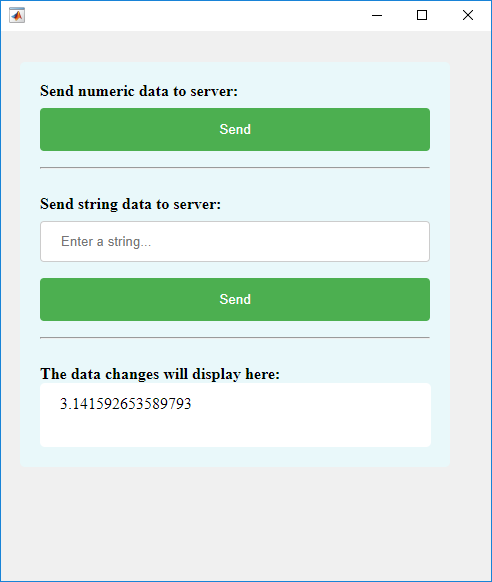

Then, set the `DataChangedFcn` property to a callback that displays the data in the Command Window each time new data is received. For example, type “Hello World” into the edit field and send it to the server. The HTML component updates the display in the app, and MATLAB displays the string in the command window.

h.DataChangedFcn = @(src,event)disp(h.Data);

*Copyright 2019 The MathWorks, Inc.*